The spike datafile contains 50 combs of 7 or 8 teeths in spike_spike{}, 50 white in spike_white{}, and 1 black in spike_black.

load('spike_0615.mat','spike_black','spike_white','spike_spike')

Show all the combs

clf
i = 27

i = 27

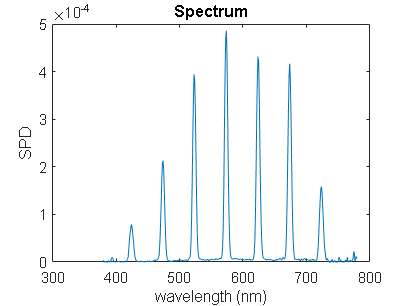

spike_spike{i}.plot;


%
% calculate the reflectance
%
spike_reflectance = {};
for i = 1:50
    spike_reflectance{i} = (spike_spike{i}-spike_black)./(spike_white{i}-spike_black);
end

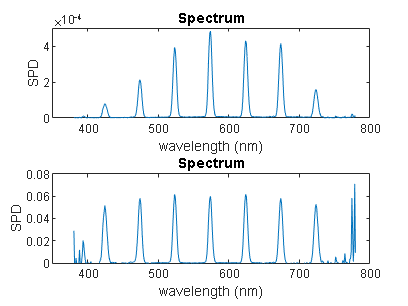

%
% visualize
%
clf
i = 27;
subplot(2,1,1)
spike_spike{i}.plot;
axis([350 800 0 5e-4])
subplot(2,1,2)
spike_reflectance{i}.plot;
axis([350 800 0 0.08])

%
% break the combs
%

comb_array = zeros(750,780);

for i = 1:50
    % decide the x values
    wl_range = [400+(i-1)*1:50:750];
    wl_range_n = length(wl_range);

    % take one curve
    comb = spike_reflectance{i};

    % convert to real wavelength
    comb_real = zeros(1,780);
    comb_real(1,380:780) = comb.amplitude;

    % iterate each spike
    for j = 1:wl_range_n
        wl = wl_range(j);
        wl_width = 25;

        comb_array(wl,wl-wl_width:wl+wl_width) = comb_real(1,wl-wl_width:wl+wl_width);
    end

end

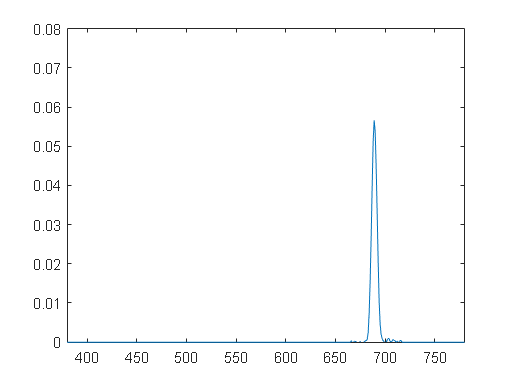

%
% visualize
%
clf
i = 691;
plot(comb_array(i,:))
axis([380 780 0 0.08])

% 6/3/2022
%
% link column with spectrum
%
col_spec = zeros(1024,401);

% mapping between column and wavelength from previous findings
col_center = [72 202 327 454 583 708 834 956];
wl_center = [400 450 500 550 600 650 700 750];

% interpolate columns between 72 and 956
for col_i = 72:956
    wl_i = round(interp1(col_center,wl_center,col_i,'linear'));
    spec = comb_array(wl_i,:);
    col_spec(col_i,:) = spec(380:780);
end


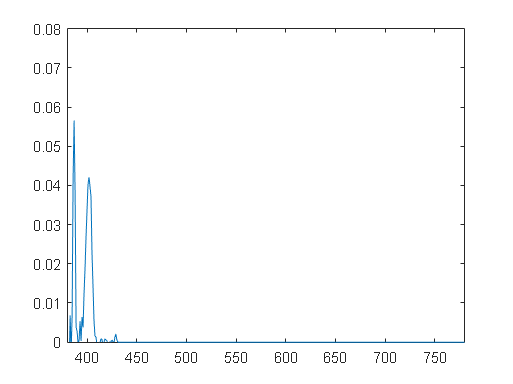

%
% visualize
%
clf
i = 86;
plot(380:780,col_spec(i,:))
axis([380 780 0 0.08])

save('col_spec_0615.mat','col_spec')